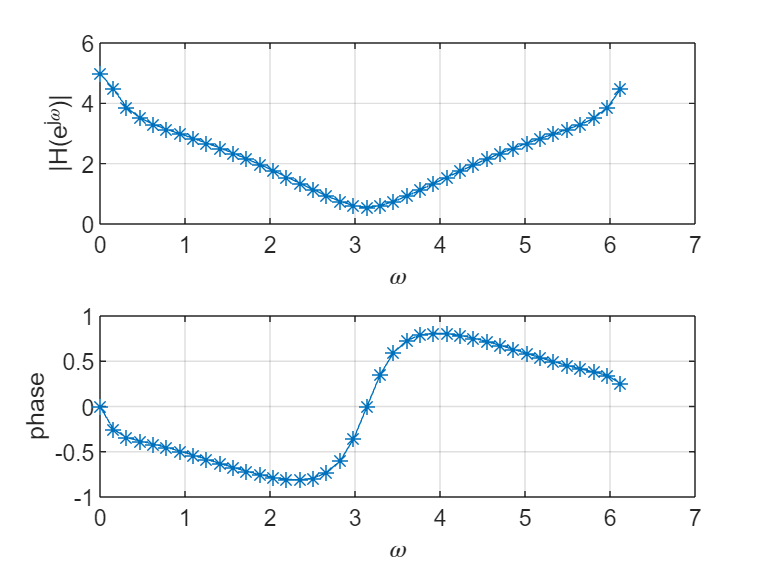

clc,clear,close all;
a=[1 -0.8];
b=[2 0 -1];
[H omega]=freqz(b,a,40,"whole");
figure;
subplot(2,1,1),plot(omega,abs(H),'*-');
xlabel('\omega'),ylabel('|H(e^{j\omega})|'),grid;
subplot(2,1,2),plot(omega,angle(H),'*-');
xlabel('\omega'),ylabel('phase'),grid;

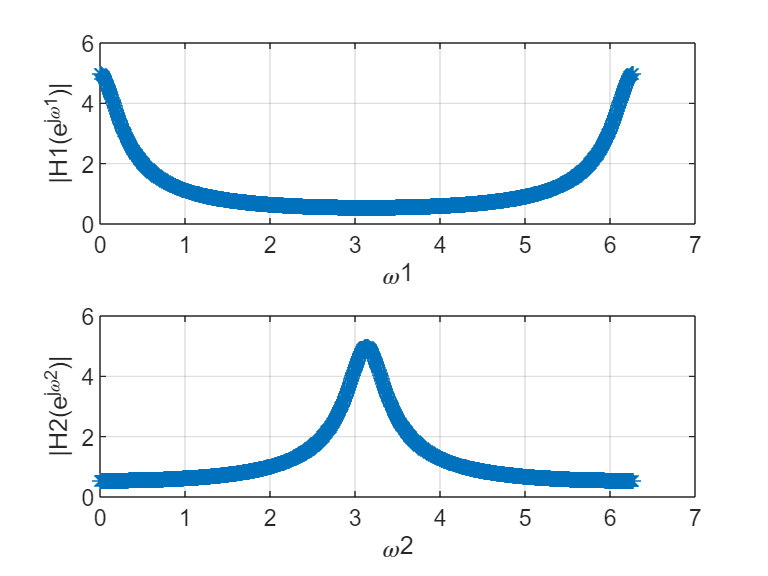

clc,clear,close all;
a1=[1 -0.8];
b1=[1];
a2=[1 0.8];
b2=[1];
[H1 omega1]=freqz(b1,a1,1024,'whole');
[H2 omega2]=freqz(b2,a2,1024,'whole');
figure;
subplot(2,1,1),plot(omega1,abs(H1),'*-');
xlabel('\omega1'),ylabel('|H1(e^{j\omega1})|'),grid;
subplot(2,1,2),plot(omega2,abs(H2),'*-');
xlabel('\omega2'),ylabel('|H2(e^{j\omega2})|'),grid;

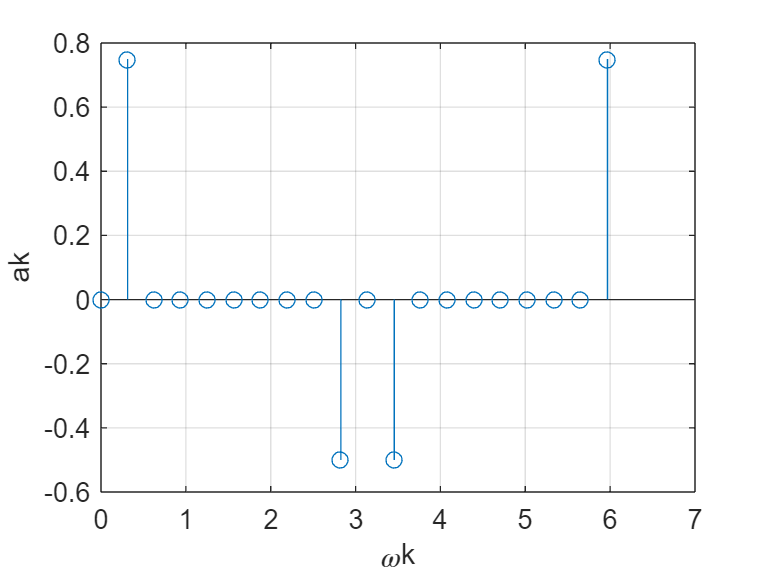

clc,clear,close all;
k=0:19;
omegak=k*pi/10;
ak=[0 0.75 zeros(1,7) -0.5 0 -0.5 zeros(1,7) 0.75];
figure;
stem(omegak,ak),xlabel('\omegak'),ylabel('ak'),grid,xlim([0 7]);

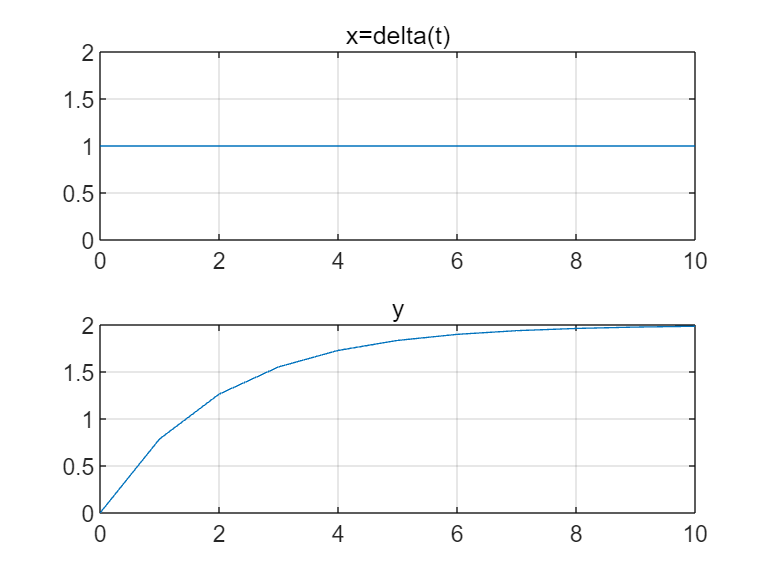

clc,clear,close all;
a=[1 0.5];
b=[1];
t=0:10;
x=ones(1,length(t));
y=lsim(b,a,x,t)';
figure;
subplot(2,1,1),plot(t,x),xlim([0 10]),title('x=delta(t)'),grid;
subplot(2,1,2),plot(t,y),xlim([0 10]),title('y'),grid;

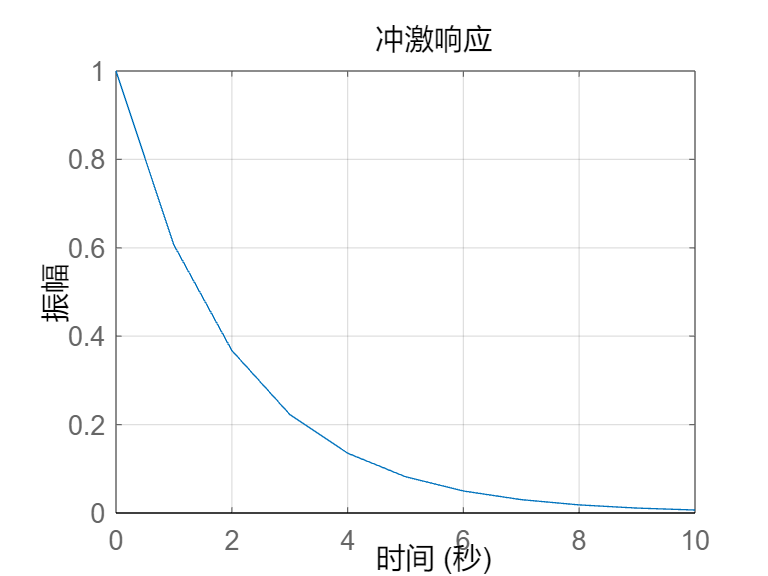

figure;
impulse(b,a,t),grid;